Question 1

[1-λ 4;

 3 2-λ]

λ^2-3λ+2-12 = λ^2-3λ-10 = (λ+2)(λ-5)

**λ1 = -2**

**λ2 = 5**

Using λ1,

[1-(-2) 4;

 3 2-(-2)]

[3 4;        1/3*R1 -> new R1

 3 4] 

[1 4/3;        

 3 4]        R2-3*R1 -> new R2

[1 4/3;        1*x+4/3y=0 --> 1*x=-4/3y

 0 0] 

**[x        =    [-4/3**

**y]        =    1]**

Using λ2,

[1-(5) 4;

 3 2-(5)]

[-4 4;        -1/4*R1 -> new R1

 3 -3]

[1 -1;        

 3 -3]        R2-3*R1 -> new R2

[1 -1;        1*x-1*y=0 --> 1*x=1*y

 0 0]

**[x        =    [1**

**y]        =    1]**

Question 2

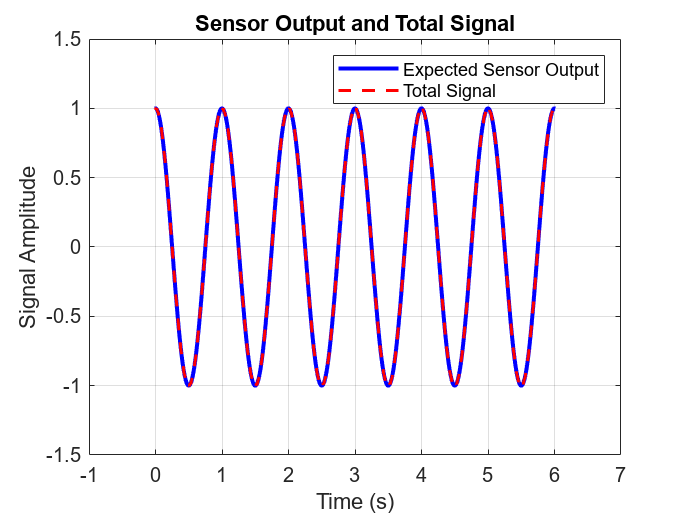

%a
t = -0.01:0.01:6.01;
f = cos(2*pi*t);
tot_signal = cos(2*pi*t) + 0.01*sin(120*pi*t);

figure;
plot(t, f, 'b-', 'LineWidth', 2);
hold on;
plot(t, tot_signal, 'r--', 'LineWidth', 1.5);
legend('Expected Sensor Output', 'tot Signal');
xlabel('Time (s)');
ylabel('Signal Amplitude');
title('Sensor Output and tot Signal');
grid on;

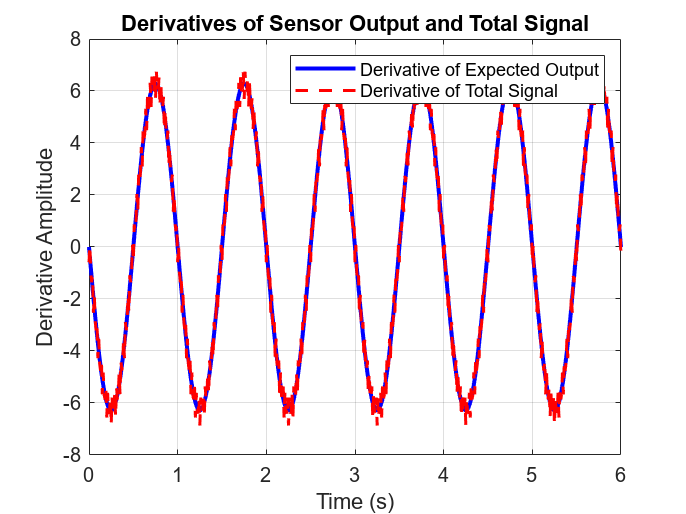


%b
h = 0.01;
df = (cos(2*pi*(t+h)) - cos(2*pi*(t-h))) / (2*h);
tot_signal_derivative = (cos(2*pi*(t+h)) + 0.01*sin(120*pi*(t+h)) - (cos(2*pi*(t-h)) + 0.01*sin(120*pi*(t-h)))) / (2*h);

valid_indices = t >= 0 & t <= 6;
t_valid = t(valid_indices);
df_valid = df(valid_indices);
tot_signal_derivative_valid = tot_signal_derivative(valid_indices);

%c
figure;
plot(t_valid, df_valid, 'b-', 'LineWidth', 2);
hold on;
plot(t_valid, tot_signal_derivative_valid, 'r--', 'LineWidth', 1.5);
legend('Derivative of Expected Output', 'Derivative of tot Signal');
xlabel('Time (s)');
ylabel('Derivative Amplitude');
title('Derivatives of Sensor Output and tot Signal');
grid on;

d

To reduce the effect of the noise on the computed derivative of the tot signal would be to use a low-pass filter on the signal before differentiation.

Question 3

%a,b,c,d
int_025 = trapz(t(t>=0 & t<=0.25), tot_signal(t>=0 & t<=0.25));
int_050 = trapz(t(t>=0 & t<=0.5), tot_signal(t>=0 & t<=0.5));
int_075 = trapz(t(t>=0 & t<=0.75), tot_signal(t>=0 & t<=0.75));
int_100 = trapz(t(t>=0 & t<=1), tot_signal(t>=0 & t<=1));

%Bonus
int_f_025 = trapz(t(t>=0 & t<=0.25), f(t>=0 & t<=0.25));
int_f_050 = trapz(t(t>=0 & t<=0.5), f(t>=0 & t<=0.5));
int_f_075 = trapz(t(t>=0 & t<=0.75), f(t>=0 & t<=0.75));
int_f_100 = trapz(t(t>=0 & t<=1), f(t>=0 & t<=1));

disp(['int of tot signal from 0 to 0.25 s: ', num2str(int_025)]);

Integral of total signal from 0 to 0.25 s: 0.1591


disp(['int of tot signal from 0 to 0.5 s: ', num2str(int_050)]);

Integral of total signal from 0 to 0.5 s: 3.8164e-17


disp(['int of tot signal from 0 to 0.75 s: ', num2str(int_075)]);

Integral of total signal from 0 to 0.75 s: -0.1591


disp(['int of tot signal from 0 to 1 s: ', num2str(int_100)]);

Integral of total signal from 0 to 1 s: -3.8164e-17



disp(['int of expected output from 0 to 0.25 s: ', num2str(int_f_025)]);

Integral of expected output from 0 to 0.25 s: 0.1591


disp(['int of expected output from 0 to 0.5 s: ', num2str(int_f_050)]);

Integral of expected output from 0 to 0.5 s: 2.4286e-17


disp(['int of expected output from 0 to 0.75 s: ', num2str(int_f_075)]);

Integral of expected output from 0 to 0.75 s: -0.1591


disp(['int of expected output from 0 to 1 s: ', num2str(int_f_100)]);

Integral of expected output from 0 to 1 s: -3.1225e-17
